# **Task:**  Explore a 2-dof Mechanical System, Resonance and ANTI-resonance

 Can a 2-dof Mechanical system be assembled such that the position of the ${\bm{H}}_{11} \left(\omega \right)$ **ANTI-Resonance** can be placed at a desired location ?

## 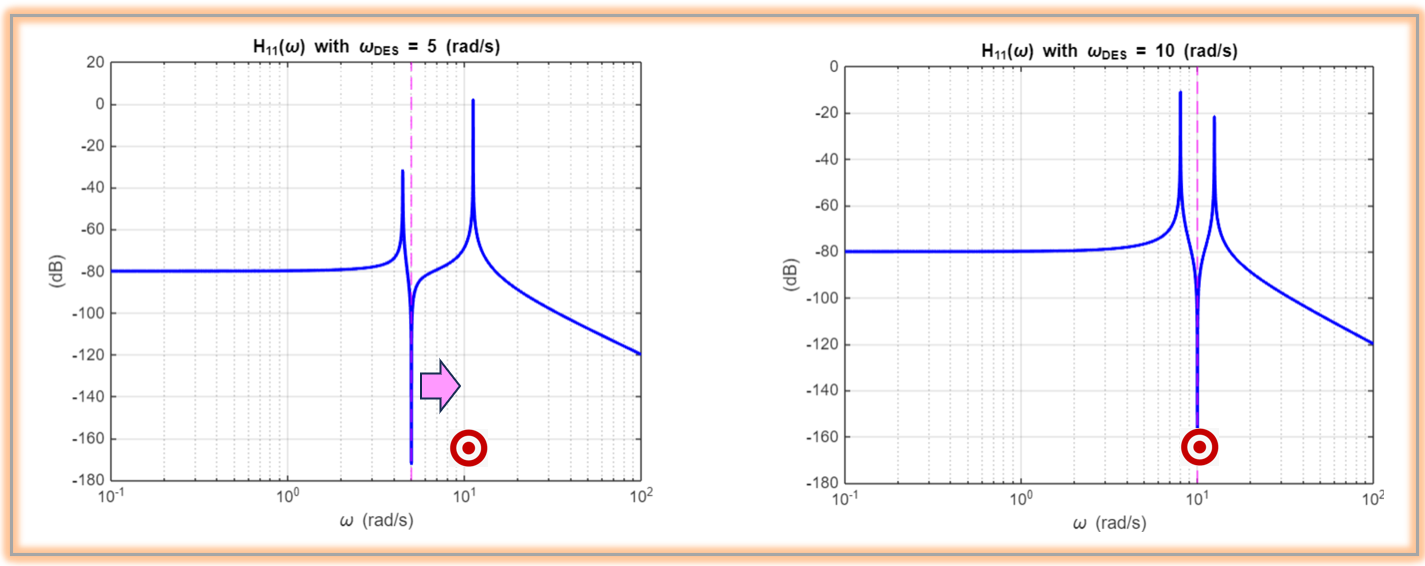

`Bradley Horton: bhorton@mathworks.com`

## Background

- See [`bh_FUNDAMENTALS_ABSORBER_background.pdf `](matlab:  winopen bh_fundamentals_absorber_background.pdf)for some revision on the standard vibration Absorber theory

- See **Appendix(A):  Representing Dynamic systems** for a refresher on how we can represent Linear dynamic systems

## Mechanical:    a 2-dof system

Consider the following undamped 2-dof system:

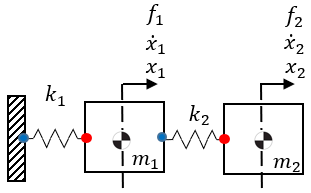

The **Undamped Mechanical equations of motion** for this system are:

- $\pmatrix{
m_1 & 0 \cr
0 & m_2 \cr
}$$. \pmatrix{
\ddot{x}_1 \cr
\ddot{x}_2 \cr
}$  +  $\pmatrix{
(k_1 + k_2) & -k_2 \cr
-k_2 & k_2 \cr
}$$. \pmatrix{
{x}_1 \cr
{x}_2 \cr
}$= $\pmatrix{
{f}_1 \cr
{f}_2 \cr
}$

Which we can write in matrix form as:   

- $M \ddot{x}  +   Kx = f$   where   $x \in R^{P\times1}$    and   $f \in R^{P\times1}$

And let's assume that we have a Proportionately damped matrix C defined as:

- 
$$C=\gamma \ldotp M\;\;+\;\;\beta \ldotp K$$


So the damped **Mechanical equations of motion** for this system is

- 
$$M \ddot{x}  +   C \dot{x}  +  Kx = f$$
   

## Let's explore our 2-dof Mechanical system

Clear your workspace

clear

So define the parameter values for our Mechanical system

k1 = 1e4;  % (N/m)
m1 = 1e2;  % (kg)
k2 = 1e3;  % (N/m)
m2 = 5;    % (kg)

M_MAT_fh = @(m1,m2)  [m1, 0; ...
                       0, m2 ];


K_MAT_fh = @(k1,k2)  [ (k1+k2), (-k2);
                         (-k2),  (k2)];

% add a "tiny" bit of damping
C_MAT_fh = @(K) 1e-6 * K;

Define the Mechanical system matrices

M = M_MAT_fh(m1,m2);
K = K_MAT_fh(k1,k2);
C = C_MAT_fh(K);

### Explore the Eigenvalue problem

- $M\ldotp \ddot{x} \;+\;K\ldotp x=0$  where $x\;\in R^{\;P\times 1}$

And let's look for a harmonic solution of the form:

- 
$$x\left(t\right)=\;\;\;\;\;\;v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$\dot{x} \left(t\right)=\;\;\;\;\;\;\;\;i\ldotp \omega \;\ldotp x\left(t\right)$$


- 
$$\ddot{x} \left(t\right)=\;-1\ldotp \omega^2 \ldotp x\left(t\right)\;$$


Then our ODE becomes:

- 
$$\left\lbrack -M\ldotp \omega^2 \;\;+\;\;K\right\rbrack \ldotp x\left(t\right)\;=\;0$$


- 
$$K\ldotp x\left(t\right)=M\ldotp x\left(t\right)\ldotp \omega^2$$


- 
$$M^{-1} \ldotp K\ldotp x\left(t\right)=\omega^2 \ldotp x\left(t\right)$$


- 
$$M^{-1} \ldotp K\ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t} =\omega^2 \ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$M^{-1} \ldotp K\ldotp v=\omega^2 \ldotp v$$


- $A\ldotp v=\lambda \;\ldotp v$       where  $\lambda =\omega^2$  and $A=M^{-1} \ldotp K$

[~, eVal] = eig(  inv(M) * K  );

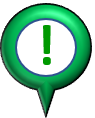So the Mechanical UNdamped  Natural frequencies are

- $\omega_n \;\;=\;\;\sqrt{\;\;\lambda \;\;\;}$   (rad/sec)

wn = sqrt(diag(eVal))

wn =     9.5685
   14.7798


### Define the State Space system

- $\pmatrix{
\ddot{x} \cr
\dot{x} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{P \times P} & 0_{P \times P} \cr
}$$. \pmatrix{
\dot{x} \cr
x \cr
}$  +  $\pmatrix{
M^{-1} \cr
0_{P \times P} \cr
}.f$

- $y=G\ldotp z\;+\;D\ldotp u$     where    $G=\;\left\lbrack \begin{array}{cc}
0_{P\times P}  & I_{P\times P} 
\end{array}\right\rbrack$    and  $D=0_{P\times P}$

A = [ -inv(M)*C,  -inv(M)*K;  
         eye(2),   zeros(2)    ];
B = [inv(M);zeros(2)];
G = [zeros(2), eye(2)];
D = zeros(2);

H_ss = ss(A,B,G,D,0,"Outputname",["x1","x2"],"InputName",["f1","f2"]);

### And Convert to Transfer function form

- 
$$\left\lbrack \begin{array}{c}
X_1 \left(s\right)\\
X_2 \left(s\right)
\end{array}\right\rbrack \;\;=\;\;\left\lbrack \begin{array}{cc}
H_{11} \left(s\right) & H_{12} \left(s\right)\\
H_{21} \left(s\right) & H_{22} \left(s\right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
F_1 \left(s\right)\\
F_2 \left(s\right)
\end{array}\right\rbrack \;\;$$


- 
$$\;\;\;X\left(s\right)\;\;\;\;\;\;=\;\;\left\lbrack H\left(s\right)\right\rbrack \ldotp F\left(s\right)$$


H_tf = tf(H_ss)

H_tf =   From input "f1" to output...
                  0.01 s^2 + 2e-06 s + 2
   x1:  -------------------------------------------
        s^4 + 0.00031 s^3 + 310 s^2 + 0.04 s + 2e04
 
                        2e-06 s + 2
   x2:  -------------------------------------------
        s^4 + 0.00031 s^3 + 310 s^2 + 0.04 s + 2e04
 
  From input "f2" to output...
                        2e-06 s + 2
   x1:  -------------------------------------------
        s^4 + 0.00031 s^3 + 310 s^2 + 0.04 s + 2e04
 
                 0.2 s^2 + 2.2e-05 s + 22
   x2:  -------------------------------------------
        s^4 + 0.00031 s^3 + 310 s^2 + 0.04 s + 2e04
 
Continuous-time transfer function.


### What are the system POLES 

Extract the SYSTEM poles

- see the DOC for [`damp`](matlab: doc damp)

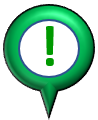 These should be:

- $\lambda_1 \;\;=\;\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_1 \;\;=\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$

- $\lambda_2 \;\;=\;\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_2 \;\;=\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$

[wn, zeta, p]  = damp(H_tf);
array2table([wn, zeta, p], "VariableNames",["Undamped_wn","DampingRatio","poles"])

ans = 8×3 table
    Undamped_wn    DampingRatio           poles       
    ___________    ____________    ___________________

      9.5685        4.7843e-06     -4.5779e-05+9.5685i
      9.5685        4.7843e-06     -4.5779e-05-9.5685i
      9.5685        4.7843e-06     -4.5779e-05+9.5685i
      9.5685        4.7843e-06     -4.5779e-05-9.5685i
       14.78        7.3899e-06     -0.00010922+14.78i 
       14.78        7.3899e-06     -0.00010922-14.78i 
       14.78        7.3899e-06     -0.00010922+14.78i 
       14.78        7.3899e-06     -0.00010922-14.78i 

	Get insights using Copilot


### What is (for example) the ZEROS of $H_{11} \left(s\right)$

Extract the zeros for $H_{11} \left(s\right)$

array2table( zero(H_tf(1,1)), "VariableNames",["zeros(H11)"])

ans = 2×1 table
      zeros(H11)   
    _______________

    -0.0001+14.142i
    -0.0001-14.142i

	Get insights using Copilot


### Plot the Frequency Response  (NO Phase wrapping)

my_plot_opts = bodeoptions;
my_plot_opts.PhaseWrapping = "off";

Plot ALL of the transfer functions

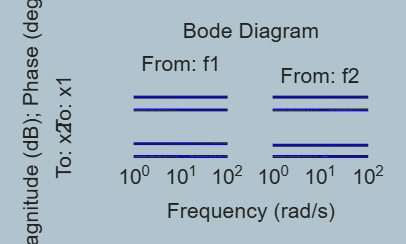

figure;  bodeplot(H_tf,'-b', {1, 1e2}, my_plot_opts); grid on

Let's just plot $H_{11} \left(s\right)$

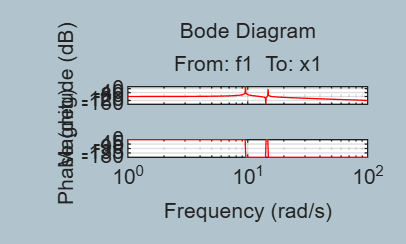

figure;  bodeplot(H_tf(1,1),'-r', {1, 1e2}, my_plot_opts); grid on

% figure;  bodeplot(H_ss(1,2),'-b', {1, 1e2}, my_plot_opts); grid on
% figure;  bodeplot(H_ss(2,1),'-m', {1, 1e2}, my_plot_opts); grid on
% figure;  bodeplot(H_ss(2,2),'-k', {1, 1e2}, my_plot_opts); grid on

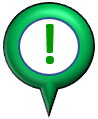 Some observations

- The ZEROS of $H_{11} \left(s\right)$ are currently at the EXCITATION frequency $\;\omega =14\ldotp 1421$(rad/sec) - as shown by the **ANTI resonance** in the bode plot

## Explore a Vibration Absorber

So let's say that we wanted to MOVE the **ANTI resonance** to some DESIRED excitation frequency $\;\omega =\omega_{\mathrm{DES}}$ (rad/sec). Choose the frequency that you want to move the ANTIRESONANCE to:

w_DES  = 5 %  (rad/sec)

w_DES = 5

Let's assume that our Spring catalogue is "short" on stiffness options ... and we're stuck with this spring:

- 
$$k_2 =2000\;\left(\frac{N}{m}\right)$$


k2_NEW = 2e3;  % (N/m)

Recall our Vibration Absorber design formula:

- 
$$m_2 \;\;=\;\;\;\frac{k_2 }{\omega_{\mathrm{DES}}^2 \;}$$


m2_NEW = k2_NEW/(w_DES^2)    % (kg)

m2_NEW = 80

Define the NEW Mechanical system

M = M_MAT_fh(m1, m2_NEW);
K = K_MAT_fh(k1, k2_NEW);
C = C_MAT_fh(K);

Define the State Space system

A = [-inv(M)*C, -inv(M)*K;  eye(2), zeros(2)];
B = [inv(M);zeros(2)];
G = [zeros(2), eye(2)];
D = zeros(2);

H_ss_new = ss(A,B,G,D,0,"Outputname",["x1","x2"],"InputName",["f1","f2"]);
H_tf_new = tf( H_ss_new );

### So ... where's the ZERO of $H_{11}$

Extract the zeros for $H_{11} \left(s\right)$

array2table( zero(H_tf_new(1,1)), "VariableNames",["zeros(H11)"])

ans = 2×1 table
     zeros(H11) 
    ____________

    -1.25e-05+5i
    -1.25e-05-5i

	Get insights using Copilot


### Plot the Frequency Response  (NO Phase wrapping)

Some DOC to review:

- [`freqresp()`](matlab:  doc freqresp) 

And plot the Frequency Response of the NEW system  $H_{11} \left(s\right)$

% my_plot_opts = bodeoptions;
% my_plot_opts.PhaseWrapping = "off";
% my_plot_opts.PhaseVisible  = "off";
% 
% figure;  
%     bodeplot(H_tf_new(1,1),'-b', {1, 1e2}, my_plot_opts); 
%         grid on

w_list  = 0.1:0.01:100;
[H_11]  = freqresp(H_tf_new(1,1), w_list);
H_11_db = 20*log10( abs(H_11(:)) );

And plot

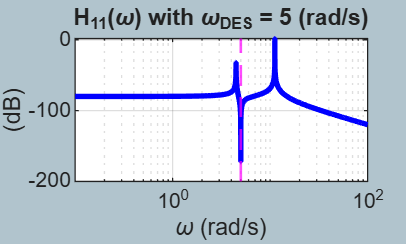

figure;
    semilogx(w_list, H_11_db, "-b", "LineWidth",2);
        grid on
        xlabel("\omega (rad/s)");
        ylabel("(dB)");
    hold on
        xline(w_DES,'--m', "LineWidth",1)
    title("H_{11}(\omega) with \omega_{DES} = "+w_DES+" (rad/s)")    

    drawnow % shouldn't have to do this

# Appendix(A):  Representing Dynamic systems

## Mechanical Transfer Function representation:

Let:

- 
$$L\left\lbrack \;x\left(t\right)\;\right\rbrack =X\left(s\right)\;\;=\;\;\left\lbrack \begin{array}{c}
X_1 \left(s\right)\\
X_2 \left(s\right)
\end{array}\right\rbrack$$


- 
$$L\left\lbrack \;f\left(t\right)\;\right\rbrack =F\left(s\right)\;=\;\;\left\lbrack \begin{array}{c}
F_1 \left(s\right)\\
F_2 \left(s\right)
\end{array}\right\rbrack$$


Taking the **Laplace transform** of the **Damped** **Mechanical equations of motion**, we get (assuming ZERO ICs):

- 
$$\left(M\ldotp s^2 \;\;+\;C\ldotp s\;+\;K\right)\ldotp X\left(s\right)\;=\;\;F\left(s\right)$$


Where our **Transfer Function** matrix is $\left\lbrack H\left(s\right)\right\rbrack$

- 
$$X\left(s\right)\;\;=\;\left\lbrack H\left(s\right)\right\rbrack \ldotp F\left(s\right)$$


The UNDAMPED eigenvalue problem can be solved 

- $\Phi \;\;\;=\;\;\;\left\lbrack \begin{array}{ccccc}
\vec{\phi_1 }  & \vec{\phi_2 }  & \vec{\phi_3 }  & \cdots  & \vec{\phi_P } 
\end{array}\right\rbrack$     where   $\vec{\phi_i } \;\in R^{P\times 1}$   

 and the Undamped NORMAL modes can be normalized such that:

-         
$$I\;\;\;\;\;=\;\;\Phi^T \ldotp M\ldotp \Phi$$
        

- ${\left\lbrack \omega_n^2 \;\;\;\right\rbrack }_{\mathrm{diag}} =\;\;\Phi^T \ldotp K\ldotp \Phi$      where   $\omega_{\mathbf{ni}}$ is the $i^{\mathrm{th}}$ ***undamped Natural frequency***

Now, Under the assumptions of Proportional damping:

- 
$$C=\gamma \ldotp M\;\;+\;\;\beta \ldotp K\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;\;{\left\lbrack 2\ldotp \zeta \ldotp \omega_n \right\rbrack }_{\mathrm{diag}} =\;\;\Phi^T \ldotp C\ldotp \Phi$$
     

Our Transfer Function matrix can be written as (see [`HERE`](matlab: edit APPENDIX_Modal_Model_Representation.mlx)):

- 
$$X\left(s\right)\;\;=\;\left\lbrack H\left(s\right)\right\rbrack \ldotp F\left(s\right)$$


- 
$$\left\lbrack H\left(s\right)\right\rbrack \;\;=\;\sum_{i=1}^P \;\;\frac{\phi_i \;\ldotp \phi_i^T }{s^2 \;\;+\;2\ldotp \zeta_i \ldotp \omega_{\mathrm{ni}} \ldotp s\;\;+\;\omega_{\mathrm{ni}}^2 }\;\;\;\;\;\;\;\;$$


**Note:**

- That   $\phi_i \;\ldotp \phi_i^T$   is a $P\times P$ matrix.  

- So $\left\lbrack H\left(s\right)\right\rbrack$ is a summation of these $P\times P$ matrices.

 Assume for our 2-dof system that:

- 
$${\vec{\phi} }_1 =\left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack \;\;\;\;\Longrightarrow \;\;\;\;\;{\vec{\phi} }_1 \ldotp {\left(\;\;{\vec{\phi} }_1 \right)}^T \;=\;\left\lbrack \begin{array}{cc}
a^2  & a\ldotp b\\
a\ldotp b & b^2 
\end{array}\right\rbrack$$


- 
$${\vec{\phi} }_2 =\left\lbrack \begin{array}{c}
c\\
d
\end{array}\right\rbrack \;\;\;\;\Longrightarrow \;\;\;\;\;{\vec{\phi} }_2 \ldotp {\left(\;\;{\vec{\phi} }_2 \right)}^T \;=\;\left\lbrack \begin{array}{cc}
c^2  & c\ldotp d\\
c\ldotp d & d^2 
\end{array}\right\rbrack$$


For our **2-dof** system ... let's just expand out our expression for $H\left(s\right)$ :

- 
$$\left\lbrack H\left(s\right)\right\rbrack \;\;=\;\left\lbrack \begin{array}{cc}
H_{11} \left(s\right) & H_{12} \left(s\right)\;\\
H_{21} \left(s\right) & H_{22} \left(s\right)
\end{array}\right\rbrack \;\;=\;\;\frac{\left\lbrack \phi_1 \;\ldotp \phi_1^T \right\rbrack }{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;+\;\;\;\;\frac{\left\lbrack \phi_2 \;\ldotp \phi_2^T \right\rbrack }{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }$$
 

- 
$$\left\lbrack H\left(s\right)\right\rbrack \;\;=\;\left\lbrack \begin{array}{cc}
H_{11} \left(s\right) & H_{12} \left(s\right)\;\\
H_{21} \left(s\right) & H_{22} \left(s\right)
\end{array}\right\rbrack \;\;=\;\;\;\;\;\frac{\left\lbrack \begin{array}{cc}
a^2  & a\ldotp b\\
a\ldotp b & b^2 
\end{array}\right\rbrack }{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;\;\;+\;\;\;\;\;\;\frac{\;\left\lbrack \begin{array}{cc}
c^2  & c\ldotp d\\
c\ldotp d & d^2 
\end{array}\right\rbrack }{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }\;\;\;\;\;\;\;\;\;\;\;$$


Form a common denominator and add these things together:

- 
$$\left\lbrack H\left(s\right)\right\rbrack \;\;=\;\left\lbrack \begin{array}{cc}
H_{11} \left(s\right) & H_{12} \left(s\right)\;\\
H_{21} \left(s\right) & H_{22} \left(s\right)
\end{array}\right\rbrack \;\;=\;\;\;\;\;\;\frac{\left\lbrace \left\lbrack \begin{array}{cc}
a^2  & a\ldotp b\\
a\ldotp b & b^2 
\end{array}\right\rbrack \ldotp \left(s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 \right)\right\rbrace \;\;\;\;+\;\;\;\;\;\left\lbrace \left\lbrack \begin{array}{cc}
c^2  & c\ldotp d\\
c\ldotp d & d^2 
\end{array}\right\rbrack \ldotp \left(s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 \right)\right\rbrace }{\left(s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 \right)\ldotp \left(s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 \right)}\;\;\;\;\;\;\;\;\;\;\;$$


So the 4 **SYSTEM poles** are:

- $\lambda_1 \;\;=\;\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_1 \;\;=\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$

- $\lambda_2 \;\;=\;\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_2 \;\;=\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$

**What about the ZEROS ?**

We don't have "system" zeros, rather each element of the transfer function matrix will have it's own zeros.  For example the ZEROS of $H_{11} \left(s\right)$ are found from solving the equation:

- 
$$H_{11} \left(s\right)\;\;=\;\;\;0\;\;\;=\left\lbrace a^2 \;\ldotp \left(s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 \right)\right\rbrace \;\;\;\;+\;\;\;\;\;\left\lbrace c^2 \;\ldotp \left(s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 \right)\right\rbrace$$


## State Space representation:

Our Mechanical equations of motion can also be expressed as a $1^{\mathrm{st}}$ order system  - usually referred to as a State Space representation.

First, recall our damped Mechanical equations of motion:

- $M \ddot{x}  +   C \dot{x}  +  Kx = f$      where   $x \in R^{P\times1}$    and   $f \in R^{P\times1}$

These Mechanical equations of motion can be expressed as the $1^{\mathrm{st}}$ order system :

- $\pmatrix{
\ddot{x} \cr
\dot{x} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{P \times P} & 0_{P \times P} \cr
}$$. \pmatrix{
\dot{x} \cr
x \cr
}$  +  $\pmatrix{
M^{-1} \cr
0_{P \times P} \cr
}.f$

Which has the form:

- $\dot{z} = A . z + B.u$    where:  $z\;=\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 \\
x_1 \\
x_2 
\end{array}\right\rbrack \;\;=\;\;\left\lbrack \begin{array}{c}
\dot{\bm{x}} \\
\bm{x}
\end{array}\right\rbrack \;\in \;\;R^{2P\times 1}$   **and**    $B = \pmatrix{
M^{-1} \cr
0_{P \times P} \cr
}$    **and**    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{P \times P} & 0_{P \times P} \cr
}$   **and**   $u=f$

And let's just measure the displacements such that

- $y=\;\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \;\;\;\;\Longrightarrow \;\;\;\;\;$$y=G\ldotp z\;+\;D\ldotp u$     where    $G=\;\left\lbrack \begin{array}{cc}
0_{P\times P}  & I_{P\times P} 
\end{array}\right\rbrack$    and  $D=0_{P\times P}$

**Note:  **the state space system represented by the matrices $A,B,G,D$ is equivalent to the Mechanical Transfer Function representation derived earlier. And in fact we can convert the State space system into a transfer function system also (recall $D=0_{P\times P}$):

- 
$$\dot{z} =A\ldotp z\;+B\ldotp u\;\;\;\;\;\;\Longrightarrow \;\;\;s\ldotp Z\left(s\right)=A\ldotp Z\left(s\right)+B\ldotp F\left(s\right)\;\;\Longrightarrow \;\;\left(s\ldotp I-A\right)\ldotp Z\left(s\right)=B\ldotp F\left(s\right)$$
 

- 
$$y=G\ldotp z\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;Y\left(s\right)=X\left(s\right)=G\ldotp Z\left(s\right)\;=\;G\ldotp {\left(s\ldotp I-A\right)}^{-1} \ldotp B\ldotp F\left(s\right)$$


So

- 
$$X\left(s\right)=\left\lbrack G\ldotp {\left(s\ldotp I-A\right)}^{-1} \ldotp B\right\rbrack \ldotp F\left(s\right)$$


- 
$$X\left(s\right)=\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left\lbrack H\left(s\right)\right\rbrack \;\ldotp F\left(s\right)$$
